**Задание: Вы синтезировали контур скорости в п.2 с учетом того, что контур тока был настроен на линейный оптимум. Настройте, контур тока на биноминальный оптимум и перенастройте контур скорости с учетом этого. Пришлите коэффициенты ПД-регулятора скорости. Постройте график переходного процесса**

load("data.mat")

syms Tu_s L_s s R_s

W_ui = 1/(L_s*s + R_s)

$$W\_ui = \frac{1}{R_{s}+L_{s}\,s}$$

W_bin = 1/(3*Tu_s*s*(Tu_s*s + 1))

$$W\_bin = \frac{1}{3\,{\mathrm{Tu}}_{s}\,s\,\left({\mathrm{Tu}}_{s}\,s+1\right)}$$

W_reg_crl = W_bin/W_ui

$$W\_reg\_crl = \frac{R_{s}+L_{s}\,s}{3\,{\mathrm{Tu}}_{s}\,s\,\left({\mathrm{Tu}}_{s}\,s+1\right)}$$

Моделирование работы контура тока, настроенного на биномиальный оптимум

i_target = 1;
Tmdl = 0.1;

To = 0.001;
crl.Tur = 0.5*To;
crl.Tu = crl.Tur;

crl.Ki_dg = 1/3/crl.Tu;
crl.Kd_dg = ob.R*1/(exp(crl.Tu*ob.R/ob.L)-1);
crl.Kp_dg = ob.R*1;

warning off
SimNew = sim('assignment_crl.slx','ReturnWorkspaceOutputs', 'on');

Program interruption (Ctrl-C) has been detected.

warning on

t = SimNew.out(:,1);
ia_an=SimNew.out(:,2);
ia_dg=SimNew.out(:,3);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,ia_an,'LineWidth',1)
hold on
grid on
plot(t,ia_dg,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\it i\rm,\it A')
legend('analog','digital','Location','best')
xlim([0 0.025])

**Аппроксимация апериодическим звеном**

Tmdl = 0.1;
for i = 1:10
    crl.Tz = i/10*To;  % диапазон изменения Tz
    Tzap(i) = crl.Tz;
    warning off
    SimNew = sim('assignment_crl_delay.slx','ReturnWorkspaceOutputs', 'on');
    warning on

    t = SimNew.out(:,1);
    ia_an = SimNew.out(:,2);
    ia_dg = SimNew.out(:,3);
    f(i) = trapz(t,abs(ia_dg-ia_an));  % интеграл разности между переходными функциями, рассчитанный по методу трапеции
end

Теперь строим график и ищем минимум функционала

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'LineWidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

**Синтез цифрового регулятора контура тока "методом переоборудования"**

Tmdl = 0.1;

i_target = 1;

To = 0.001;
crl.Tz = 0.3*To;
crl.Tur = 1*To;
crl.Tu = crl.Tur+crl.Tz;

crl.Ki_dg = 1/3/crl.Tu;
crl.Kd_dg = ob.R*1/(exp(crl.Tu*ob.R/ob.L)-1);
crl.Kp_dg = ob.R*1;

warning off
SimNew = sim('assignment_crl_delay.slx','ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.out(:,1);
ia_an=SimNew.out(:,2);
ia_dg=SimNew.out(:,3);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,ia_an,'LineWidth',1)
hold on
grid on
plot(t,ia_dg,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\it i\rm,\it A')
legend('analog','digital','Location','best')
xlim([0 0.03])

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = ia_dg;
y0 = y(1);
yss = y(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/crl.Tu)

Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/crl.Tu)

Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

**Настройка контура скорости**

syms crl_Tu spl_Tu s Ce kdw J
crl_W_reg = 1/(3*crl_Tu*s*(crl_Tu*s + 1))

$$crl\_W\_reg = \frac{1}{3\,{\mathrm{crl}}_{\mathrm{Tu}}\,s\,\left({\mathrm{crl}}_{\mathrm{Tu}}\,s+1\right)}$$

W_ob2 = Ce*kdw/J/s

$$W\_ob2 = \frac{\mathrm{Ce}\,\mathrm{kdw}}{J\,s}$$

W_tech = 1/(2*spl_Tu*s*(spl_Tu*s+1))

$$W\_tech = \frac{1}{2\,s\,{\mathrm{spl}}_{\mathrm{Tu}}\,\left(s\,{\mathrm{spl}}_{\mathrm{Tu}}+1\right)}$$

spl_W_reg = W_tech/W_ob2/crl_W_reg

$$spl\_W\_reg = \frac{3\,J\,{\mathrm{crl}}_{\mathrm{Tu}}\,s\,\left({\mathrm{crl}}_{\mathrm{Tu}}\,s+1\right)}{2\,\mathrm{Ce}\,\mathrm{kdw}\,{\mathrm{spl}}_{\mathrm{Tu}}\,\left(s\,{\mathrm{spl}}_{\mathrm{Tu}}+1\right)}$$

Tmdl = 0.5;
w_target = 1;
To = 0.001;

crl.Tz = 0.3*To;
crl.Tur = 1*To;
crl.Tu = crl.Tur+crl.Tz;

crl.Ki_dg = 1/3/crl.Tu;
crl.Kd_dg = ob.R*1/(exp(crl.Tu*ob.R/ob.L)-1);
crl.Kp_dg = ob.R*1;

spl.Tur = 0.5*To;
spl.Tu = spl.Tur;

spl.Kg = 3*ob.J*crl.Tu/(2*ob.Ce*ob.kdw*spl.Tu);
spl.Kp1_dg = 1;
spl.Kd1_dg = 1/(exp(To/crl.Tu)-1);
spl.Kd2_dg = spl.Kg/(exp(To/1)-1);

warning off
SimNew = sim('assignment_spl_crl.slx','ReturnWorkspaceOutputs', 'on');

Found algebraic loop containing: 
assignment_spl_crl/Electric Drive3/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
assignment_spl_crl/Electric Drive3/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
assignment_spl_crl/Digital  Current Loop/A//D C
assignment_spl_crl/Digital  Current Loop/Sum3
assignment_spl_crl/Digital  Current Loop/crl.Ki_dg


warning on

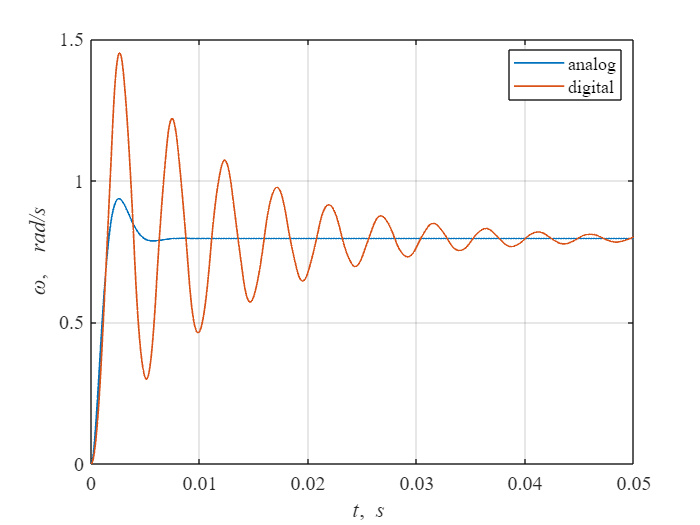

t = SimNew.out(:,1);
w_an=SimNew.out(:,2);
w_dg=SimNew.out(:,3);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,w_an,'LineWidth',1)
hold on
grid on
plot(t,w_dg,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\omega, \it rad/s')
legend('analog','digital','Location','best')
xlim([0 0.05])

**Аппроксимация апериодическим звеном**

for i = 1:20
    spl.Tz = i/10*To;  % диапазон изменения Tz
    Tzap(i) = spl.Tz;
    warning off
    SimNew = sim('new_assignment_spl_crl.slx','ReturnWorkspaceOutputs', 'on');
    warning on

    t = SimNew.out(:,1);
    w_an = SimNew.out(:,2);
    w_dg = SimNew.out(:,3);
    f(i) = trapz(t,abs(w_dg - w_an));  % интеграл разности между переходными функциями, рассчитанный по методу трапеции
end

Found algebraic loop containing: 
new_assignment_spl_crl/Electric Drive3/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
new_assignment_spl_crl/Electric Drive3/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
new_assignment_spl_crl/Digital  Current Loop/A//D C
new_assignment_spl_crl/Digital  Current Loop/Sum3
new_assignment_spl_crl/Digital  Current Loop/crl.Ki_dg


Теперь строим график и ищем минимум функционала

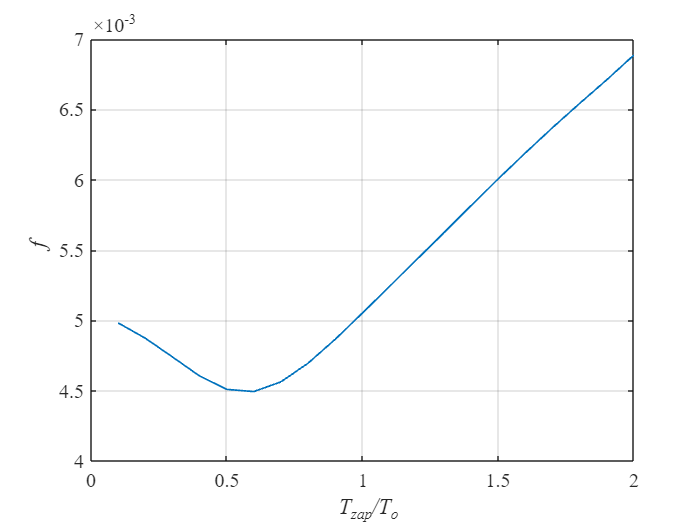

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'LineWidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

**Синтез цифрового регулятора скорости "методом переоборудования"**

Tmdl = 0.5;
w_target = 1;
To = 0.001;

crl.Tz = 0.3*To;
crl.Tur = 1*To;
crl.Tu = crl.Tur+crl.Tz;

crl.Ki_dg = 1/3/crl.Tu;
crl.Kd_dg = ob.R*1/(exp(crl.Tu*ob.R/ob.L)-1);
crl.Kp_dg = ob.R*1;

spl.Tz = 0.6*To;
spl.Tur = 0.5*To;
spl.Tu = spl.Tur + spl.Tz;

spl.Kg_an = 3*ob.J*crl.Tu/(2*ob.Ce*ob.kdw*spl.Tur);
spl.Kg = 3*ob.J*crl.Tu/(2*ob.Ce*ob.kdw*spl.Tu);
spl.Kp1_dg = 1;
spl.Kd1_dg = 1/(exp(To/crl.Tu)-1);
spl.Kd2_dg = spl.Kg/(exp(To/1)-1);

warning off
SimNew = sim('new_assignment_spl_crl.slx','ReturnWorkspaceOutputs', 'on');

Found algebraic loop containing: 
new_assignment_spl_crl/Electric Drive3/EMC/Solver Configuration/EVAL_KEY/INPUT_1_1_1
new_assignment_spl_crl/Electric Drive3/EMC/Solver Configuration/EVAL_KEY/OUTPUT_1_0
new_assignment_spl_crl/Digital  Current Loop/A//D C
new_assignment_spl_crl/Digital  Current Loop/Sum3
new_assignment_spl_crl/Digital  Current Loop/crl.Ki_dg


warning on

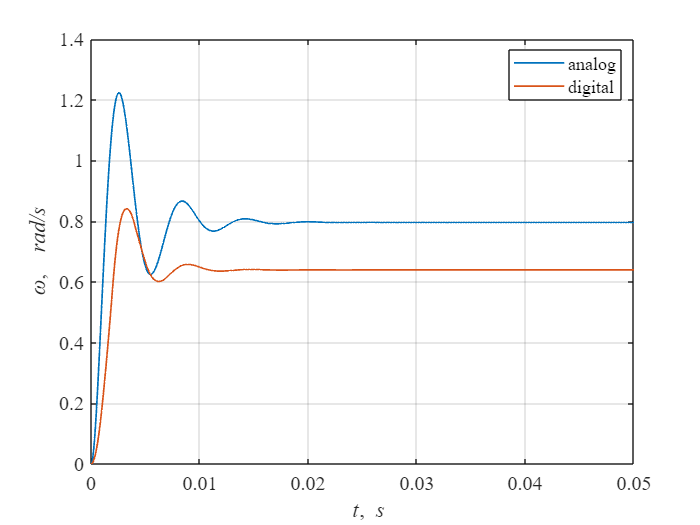

t = SimNew.out(:,1);
w_an=SimNew.out(:,2);
w_dg=SimNew.out(:,3);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,w_an,'LineWidth',1)
hold on
grid on
plot(t,w_dg,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\omega, \it rad/s')
legend('analog','digital','Location','best')
xlim([0 0.05])

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = w_dg;
y0 = y(1);
yss = y(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/crl.Tu)

Время переходного процесса tp1 для 5% зоны: 1.6*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/crl.Tu)

Время переходного процесса tp2 для 5% зоны: 5.2*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 31.5%
